# Simulate galton's example: Regression to the mean

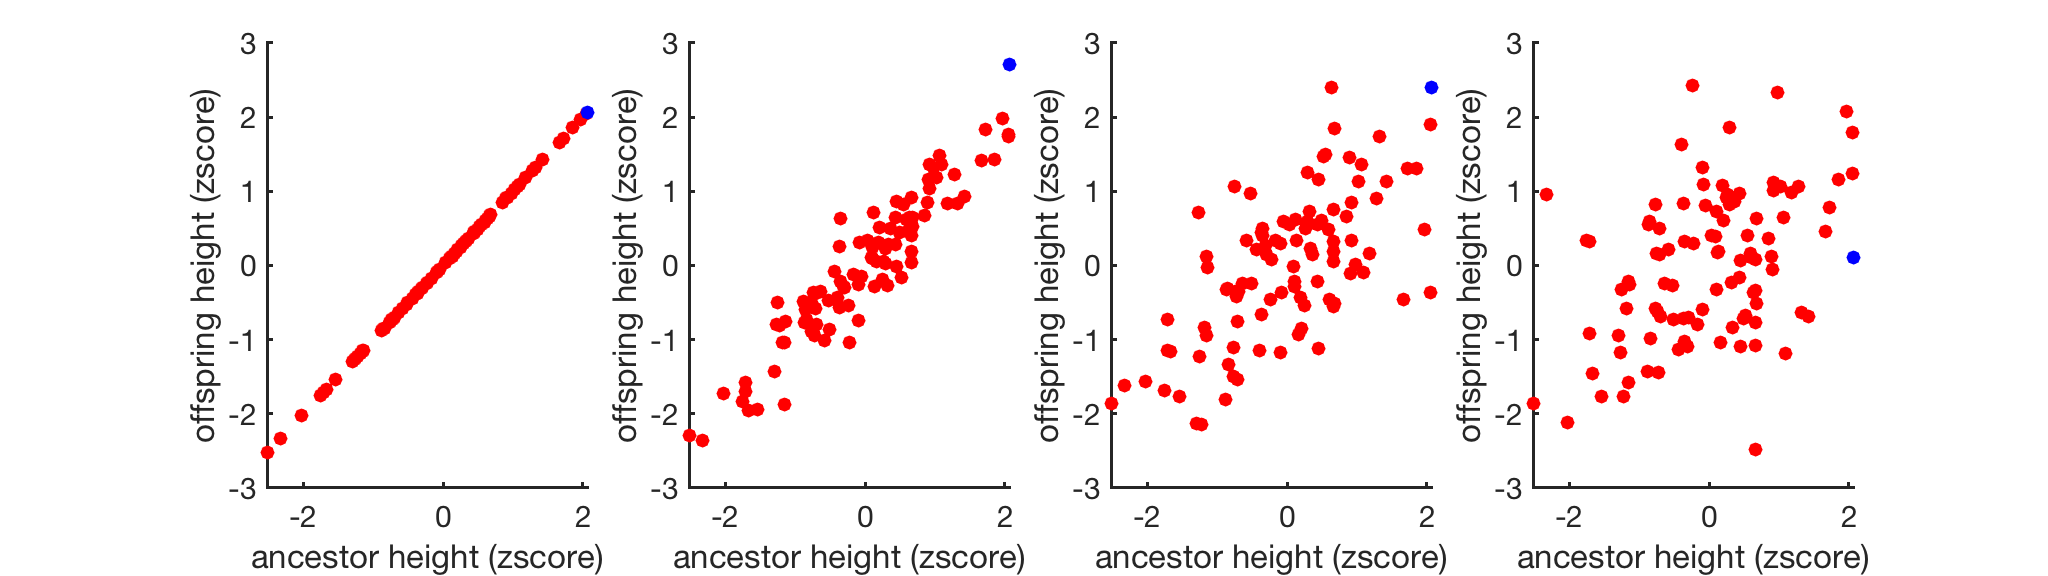

clear;
ancestor = normrnd(170, 15, 100, 1);
offspring{1} = ancestor*1.03; % no noise
offspring{2} = ancestor*1.03+normrnd(0, 5, 100,1); % add some randomness to offsprings (noise)
offspring{3} = ancestor*1.03+normrnd(0, 15, 100,1); % add more randomness 
offspring{4} = ancestor*1.03+normrnd(0, 30, 100,1); % more randomness 

% let's track the ancestor who has the maximum height, which will be marked as blue!
[~, max_idx] = max(ancestor);

figure;
screensize = get( 0, 'Screensize');
set(gcf,'Position',[0 0 screensize(3)/2.5 screensize(4)/5])
for i = 1:numel(offspring)
    subplot(1,numel(offspring),i);
    x = zscore(ancestor);
    y = zscore(offspring{i});
    scatter(x, y, 50, 'r', 'filled');
    hold on;
    scatter(x(max_idx), y(max_idx), 50, 'b', 'filled');
    set(gca, 'fontsize', 15, 'linewidth', 1.5);
    xlabel('ancestor height (zscore)');
    ylabel('offspring height (zscore)');
end